# Изучение красного смещения звезд

close all
clear variables

## Импорт данных

spectra=importdata("spectra.csv");
starNames=importdata("star_names.csv");
lambdaStart=importdata("lambda_start.csv");
lambdaDelta=importdata("lambda_delta.csv");

## Константы

lambdaPr=656.28;%нм
speedofLight=299792.458;%км\с

## Определение диапазона длин волн

nObs=size(spectra,1);
nStar=size(starNames,1);
lambdaEnd=lambdaStart+(nObs-1)*lambdaDelta;
lambda=(lambdaStart:lambdaDelta:lambdaEnd)';

## Расчет скорости

speed=rand(nStar,1);

for i=1:nStar
    s=spectra(:,i);
    [sHa,idx]=min(s);
    lambdaHa=lambda(idx);
    z=(lambdaHa/lambdaPr)-1;
    speed(i,1)=z*speedofLight;
end

## Построение графика

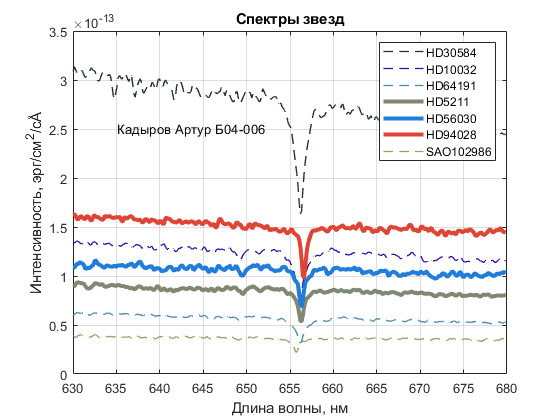

fg1=figure;
for i=1 :nStar
    s=spectra(:,i);
    if speed(i)>0
         plot(lambda,s, )
    else
         plot(lambda,s, "--",'LineWidth',1,"Color",[rand(1) rand(1) rand(1)])
    end
    set(fg1,'Visible','on');
    hold on
end 
grid on
legend(starNames)
xlabel('Длина волны, нм')
ylabel(['Интенсивность, эрг/см^2/с',char(197)])
title({'Спектры звезд'})
text(lambdaStart+5,max(spectra(:,1))*0.8,'Кадыров Артур Б04-006');
hold off

movaway =starNames(speed>0);

## Сохранение графика

saveas(fg1,'spectra.png');